# Newton Raphson Method 

**Newton's Method**, also known as **Newton-Raphson method**, named after Isaac Newton and Joseph Raphson, is a popular iterative method to find a good approximation for the root of a real-valued function *f(x) = 0.* It uses the idea that a continuous and differentiable function can be approximated by a straight line tangent to it.

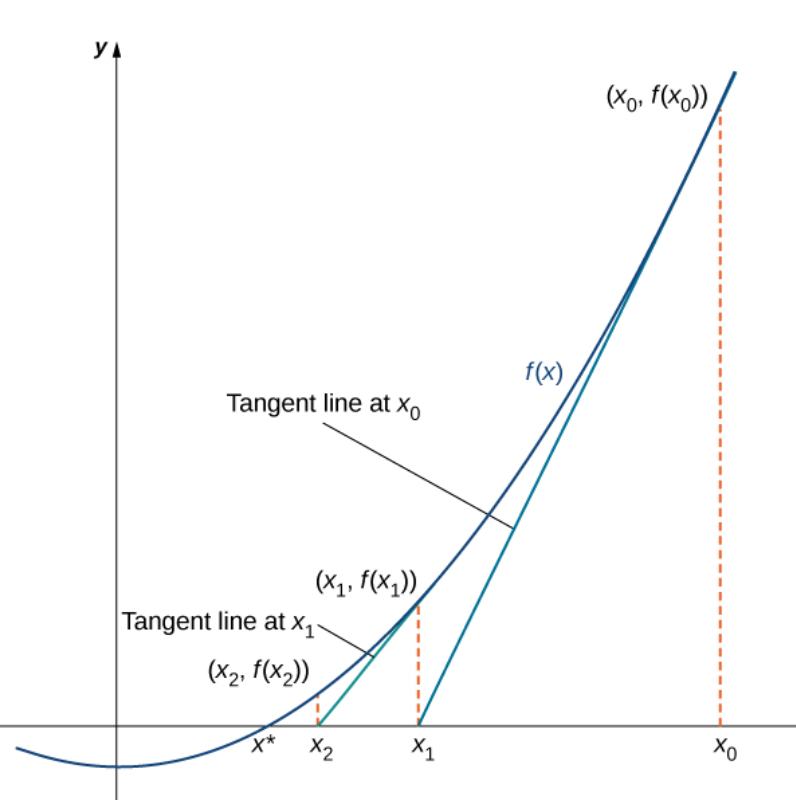

If $x_n$ is the current estimate, then the next estimate $x_{n+1}$ is given by :

## 
$$x_{n+1} =x_n -\frac{f\left(x_n \right)}{f^{\prime } \left(x_n \right)}$$


where $f^{\prime } \left(x_n \right)$ is the derivative of the function.

### **Step 1 : Defining the Function **

First step of this method is to define the function **. **We have to remember that the function must have to be differentiable and continious.Then we will input the initial guess of the root which is defined as **X(1)**.

Here we will take function as input from user which will be treated as a string and stored into  **f_input** variable.Using inline function (ignoring warning )  we have turned it into a vector which can be calculated by Matlab.

For ensuring the accuracy of the root, we have to define the accuracy(**accuracy**) .Here we have defined accuracy as approximate relative error which can be representated as 

### 
$$\textrm{accuracy}=|\frac{x_n -x_{n+1} }{x_n }|$$


For simplification of our calculation, we didnot converted the accuracy into % .So if we want 1% accuracy here the value of accuracy will be 0.001

f_input = input("Enter f(x) = ","s");           %Function of variable x
f = inline(f_input);                %using anonymous function instead of inline function
root = input ( "Initial guess of root =");
accuracy = input ( "Value of required accuracy  =");

### **Step 2 : Checking Functional Value at point a **

In this step we will use **if** statement to check that is the initial guess of the root actually a root of the function and use **return** statement to stop executing rest of the matlab script.

if (f(root) == 0 )
    fprintf("Initail guess is one of the roots\n")
    return 
end


### **Step 3 : Derivatives of the function **

For finding the roots in Newton Raphson method we have to find the derivatives of the function.We will take input the derivatives of the function as inline function .[Derivative of a function ](https://www.derivative-calculator.net/)can be found using this hyperlink.

d_input = input("Enter f'(x) = ","s");           %Function of variable x
d = inline(d_input);

### **Step 4 : Initialize the values **

First we have to inititalize some required values.To start counting our number of interation, we assigned  i= 0. As we will find our root untill we get our required accuracy ,so we will initialize the error value as height value infinity.

i = 0;
error = inf ;

### **Step 5 : Looping For finding the Roots  **

- For iteration process we will use while loop as our iteration will continue untill we achieve our required accuracy.

- As we want to print our iteration result as table, so firstly we have printed heading of the table just only when the value of iteration is 0.

- For Newton Raphson  method our new root will be $\textrm{new}\_\textrm{root}=\textrm{root}-\frac{f\left(\textrm{root}\right)}{f^{\prime } \left(\textrm{root}\right)}$ .

- We will increase the value of iteration .

- Then we will assign our **new_root** to variable **root** and finally print those values using frpintf.

while (abs (error)) > accuracy
    if i == 0
        fprintf("Iteration\tRoot\tError");

    end
    
    new_root=(root)-((f(root)/d(root)));
    i=i+1;
    error=abs((new_root-root)/root);
    root =new_root;
 
    fprintf('\n %d \t %f\t %f', i,root,error);
end

### Step 6 : Printing Results 

Finally we will print our result with required accuracy 

fprintf("The root of the function is %f",root);